# How do Radiance Measurements from Space change with Different Atmospheric gaseous profiles?

By Andrew John Buggee

## Plot the water vapor profile for every atmosphere provided by libRadTran

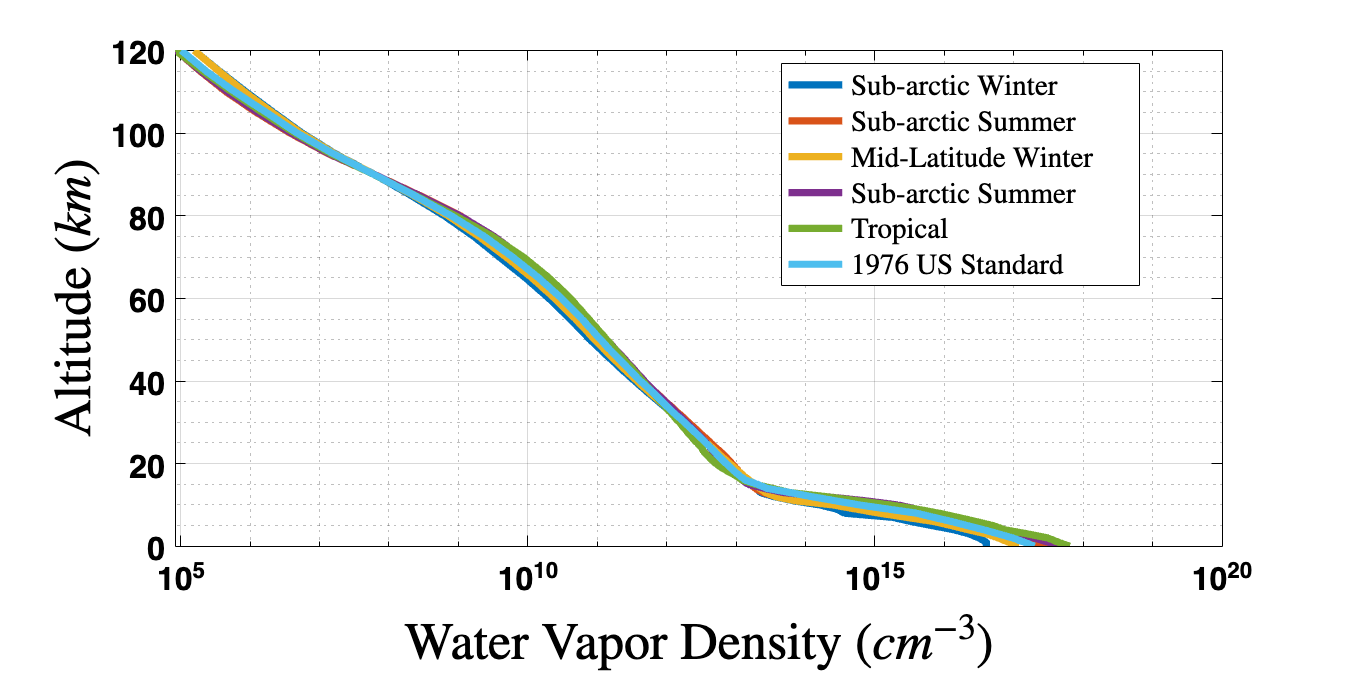

figure;

% Load the Air Force Geophysical Laboratory's Sub-Arctic Winter atmsophere
atm = read_atmos_prof_data('afglsw.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);
hold on;

% Load the Air Force Geophysical Laboratory's Sub-Arctic Summer atmsophere
atm = read_atmos_prof_data('afglss.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);

% Load the Air Force Geophysical Laboratory's Mid-Latitude Winter atmsophere
atm = read_atmos_prof_data('afglmw.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);

% Load the Air Force Geophysical Laboratory's Mid-Latitde Summer atmsophere
atm = read_atmos_prof_data('afglms.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);

% Load the Air Force Geophysical Laboratory's Tropical atmsophere
atm = read_atmos_prof_data('afglt.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);

% Load the Air Force Geophysical Laboratory's US Standar atmsophere
atm = read_atmos_prof_data('afglus.dat');
% plot the water vapor profile
semilogx(atm.H2O, atm.altitude);

grid on; grid minor
legend('Sub-arctic Winter','Sub-arctic Summer','Mid-Latitude Winter','Sub-arctic Summer',...
    'Tropical','1976 US Standard','Interpreter','latex','Location','best')
xlabel('Water Vapor Density ($cm^{-3}$)','Interpreter','latex')
ylabel('Altitude ($km$)','Interpreter','latex')
set(gcf,'Position', [0 0 750, 375])

The 5 water vapor profiles do not differ all tha much in vertical structure. They appear to differ in magnitude but have similar vertical structure. 

## Modify Total Column Water Vapor

addLibRadTran_paths


% Define the folder name,

folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval/',...
    'LibRadTran/libRadtran-2.0.4/testing_UVSPEC/'];




The command *mol_modify* sets the total number of molecules over a column of $1 \; cm^{2}$. This can also be defined in $mm$ of preipitability. Meaning, if the column of gas condensed over a $mm^2$ this liquid would have a height of $x\; mm$. Let's vary the total column of water vapor from 0 to $75 \; mm$, which is the max value displayed by *worldview.earthdata.nasa.gov*.  

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 0;                        % degree

% define the viewing zenith angle
vza = 0;                        % degree

% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")

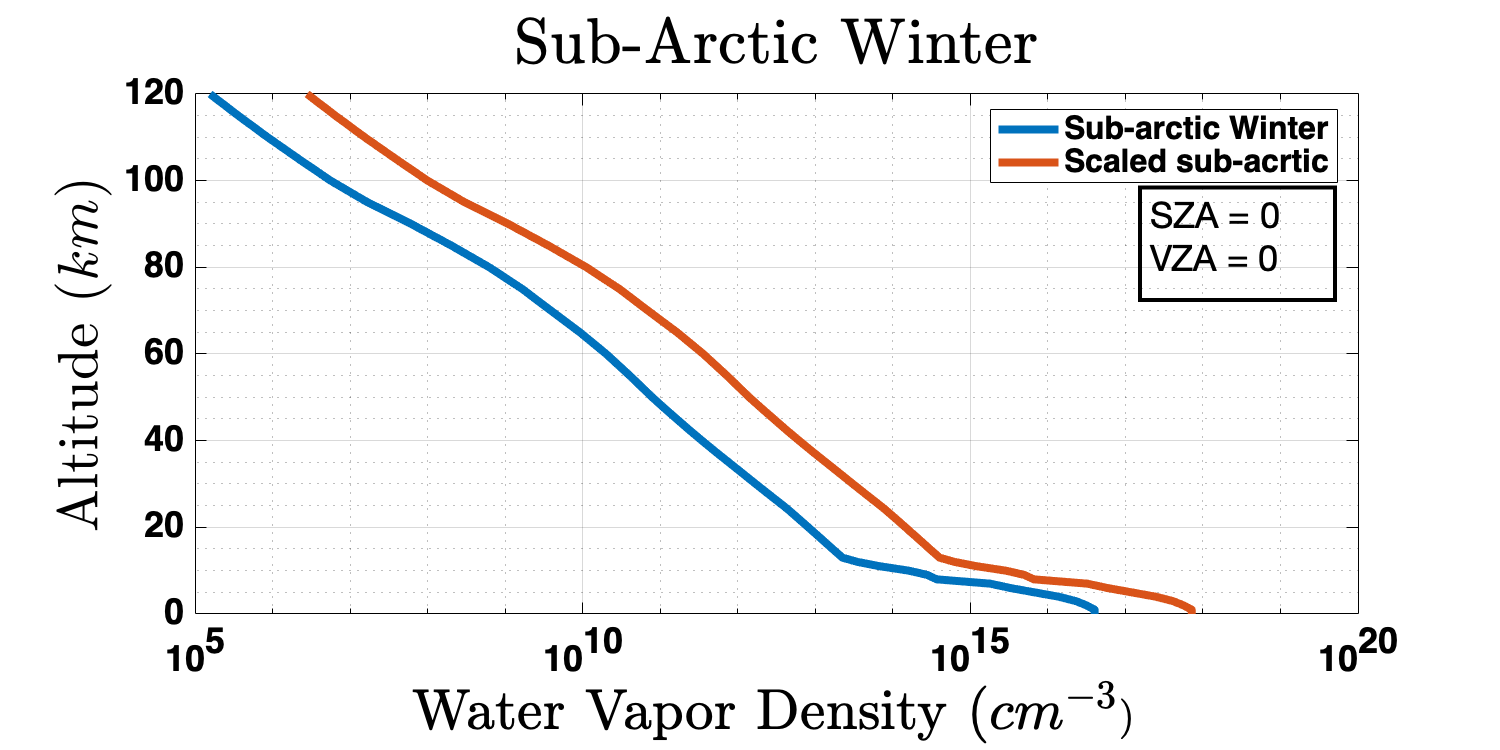

% ------- Make Plots! -------

% How does the scaled profile of water vapor compare with the standard
% profile?

% Load the Air Force Geophysical Laboratory's Sub-Arctic Winter atmsophere
atm = read_atmos_prof_data(atm_file);

% Load the 75MM scaled H2O profile using mol_modify
load("sub_arctic_winter_scaled2_75MM_H2O.mat", "sub_acrtic_winter_scaled2_75MM_H2O");

figure;
semilogx(atm.H2O, atm.altitude);
hold on;
semilogx(sub_acrtic_winter_scaled2_75MM_H2O, atm.altitude);
grid on; grid minor
% Create textbox of solar and viewing zenith angles
annotation('textbox',[0.76 0.6 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
legend('Sub-arctic Winter','Scaled sub-acrtic','Location','best')
xlabel('Water Vapor Density ($cm^{-3}$)','Interpreter','latex')
ylabel('Altitude ($km$)','Interpreter','latex')
title('Sub-Arctic Winter','Interpreter','latex')
set(gcf,'Position', [0 0 750, 375])

The blue curve is the original $H_2O$ vapor profile in the AFGL Sub-Arctic Winter atmosphere. The red curve is the modifed water vapor profile, so that the toal precipitable water is $75\;mm$. The scaled curve appears to maintain the same vertical structure as the original curve. 

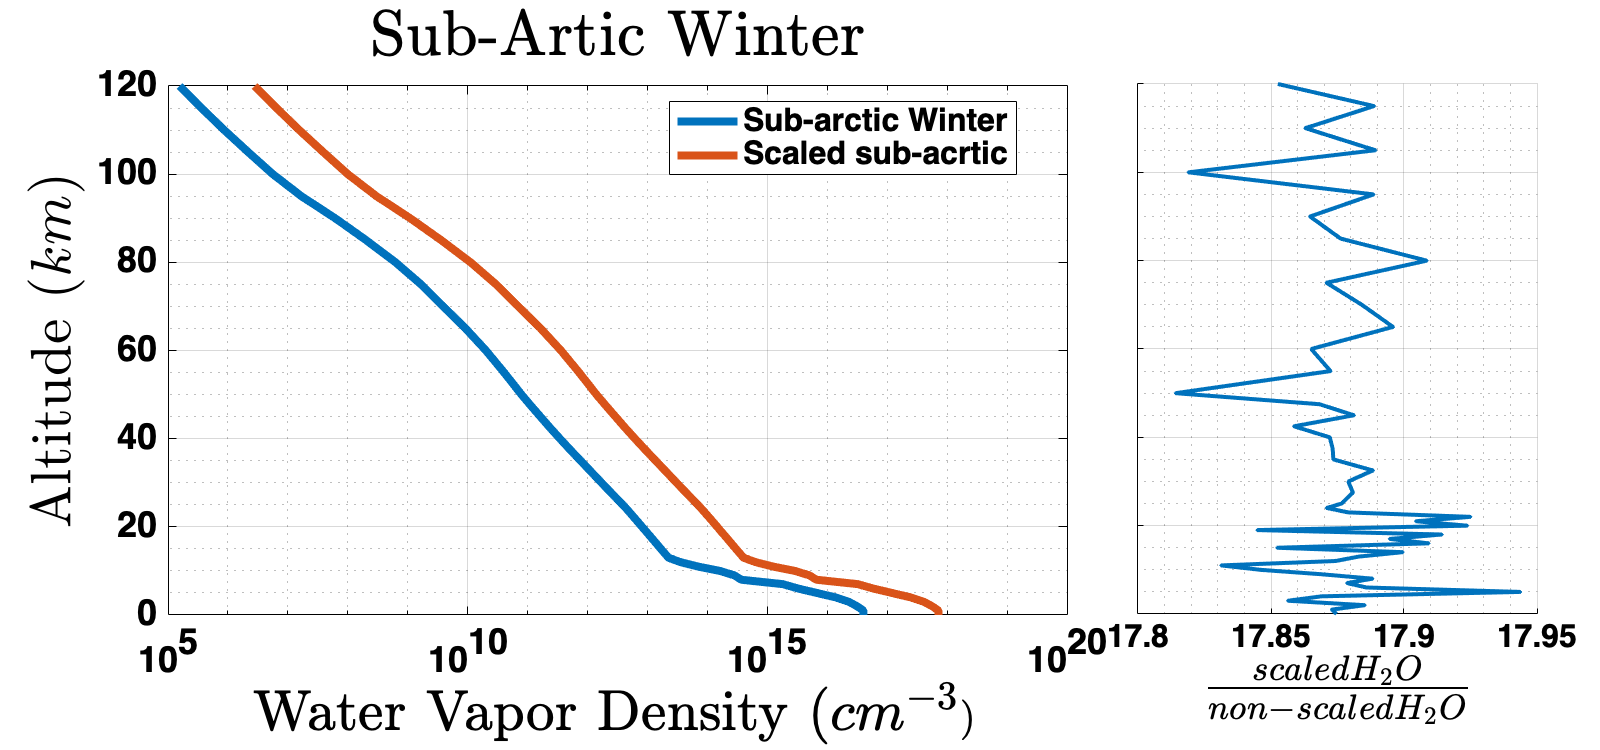

% What is the multiplicative factor between the two curves above?

% Create figure
figure1 = figure;

% Create first plot axes
axes1 = axes('Parent',figure1,'Position',[0.105263157894737 0.17934009532638 0.56140350877193 0.706497455732471]);
semilogx(atm.H2O, atm.altitude);
hold on;
semilogx(sub_acrtic_winter_scaled2_75MM_H2O, atm.altitude);
grid on; grid minor

legend('Sub-arctic Winter','Scaled sub-acrtic','Location','best')
xlabel('Water Vapor Density ($cm^{-3}$)','Interpreter','latex')
ylabel('Altitude ($km$)','Interpreter','latex')
title('Sub-Artic Winter','Interpreter','latex')

% Create second plot axes
axes2 = axes('Parent',figure1,'Position',[0.711111111111111 0.18187816639237 0.249514221158957 0.706497455732471]);
hold(axes2,'on');
semilogx(sub_acrtic_winter_scaled2_75MM_H2O./atm.H2O, atm.altitude, 'LineWidth', 2);
% Get rid of the y axis tick labels
set(axes2, 'YTickLabel',{})
xlabel('$\frac{scaled H_{2}O}{non-scaled H_{2}O}$','Interpreter','latex')
grid on; grid minor
set(gcf,'Position', [0 0 800, 375])

Notice that the multiplicative factor between the two cuvres is not constant! So some variation of the multiplicative factor is applied so that that relative shape can be conserved. 

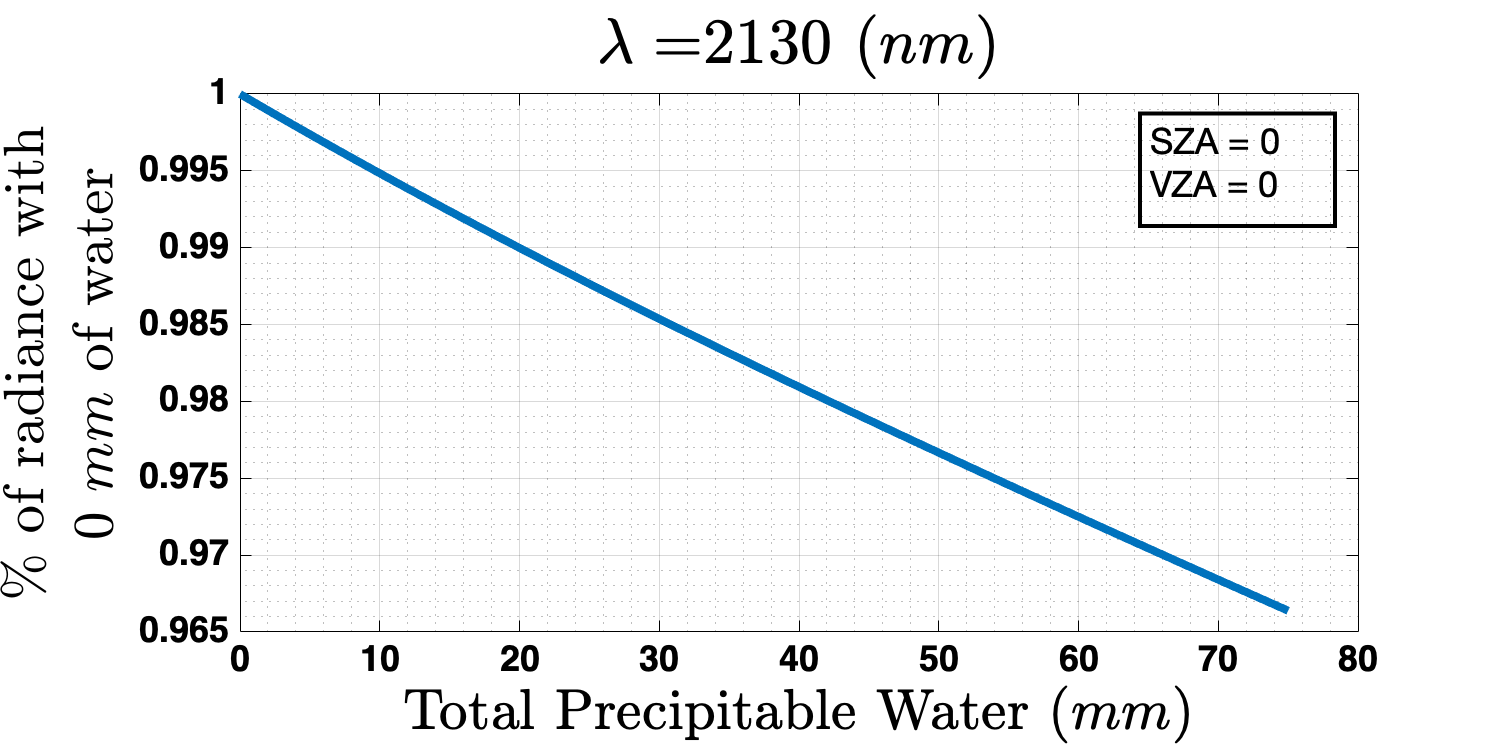

% How does the radiance measured at TOA change with the scaled total
% precipitable water?

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of radiance with',newline,' 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',4)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox of solar and viewing zenith angles
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

Wow, the radiance measured by our satellite in space barely changes! This was computed wtih a cloudless atmosphere and with a sensor and solar zenith angle of 0 degrees. How does this change as the solar zenith angle incrases?

#### Same calcualtions as above, but now the solar zenith angle is 45$\degree$ instead of 0$\degree$ 

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree

% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")


#### Makes Plots!

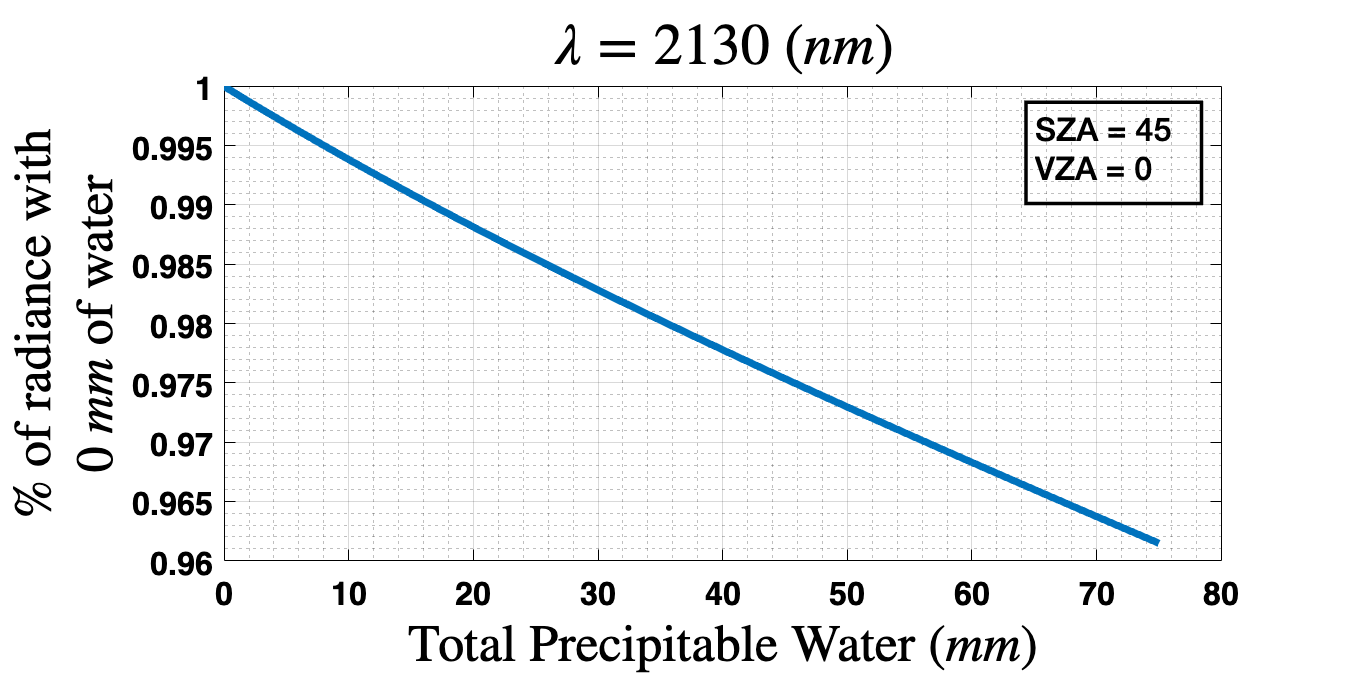

% How does the radiance measured at TOA change with the scaled total
% precipitable water?
figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of radiance with',newline,' 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',4)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

So the solar zenith angle doesn't dramatically change the amount of radaince measured in space due to a change in the total amount of percipitable water (total water vapor) for a cloudless atmosphere.

#### How does the radiance change for a wavelength in the visible region where water vapor absorption is negligible?

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 645;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree

% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")


#### Make Plots

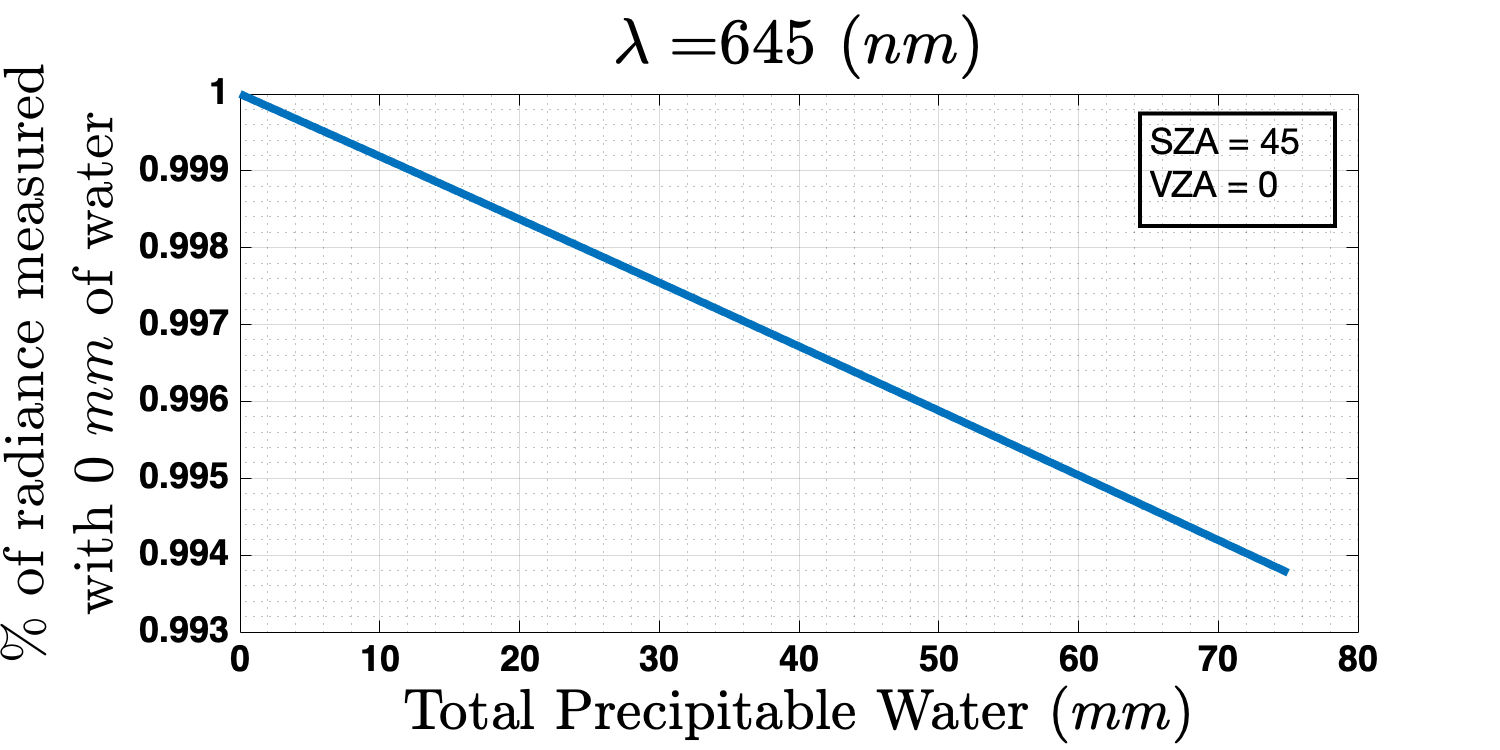

% How does the radiance measured at TOA change with the scaled total
% precipitable water?

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'with 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',4)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

Measured radiance changed even less! This is what I predicted, that the scattering cross section of water vapor in the visible range is extremely low. This I guessed was true because humans cannot see water vapor, only condensed liquid water. So even massive amounts of atmospheric water vapor don't change our measurements much.

#### How does the radiance change for a wavelength with a high water vapor absorption coefficient?

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 1900;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree


% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")

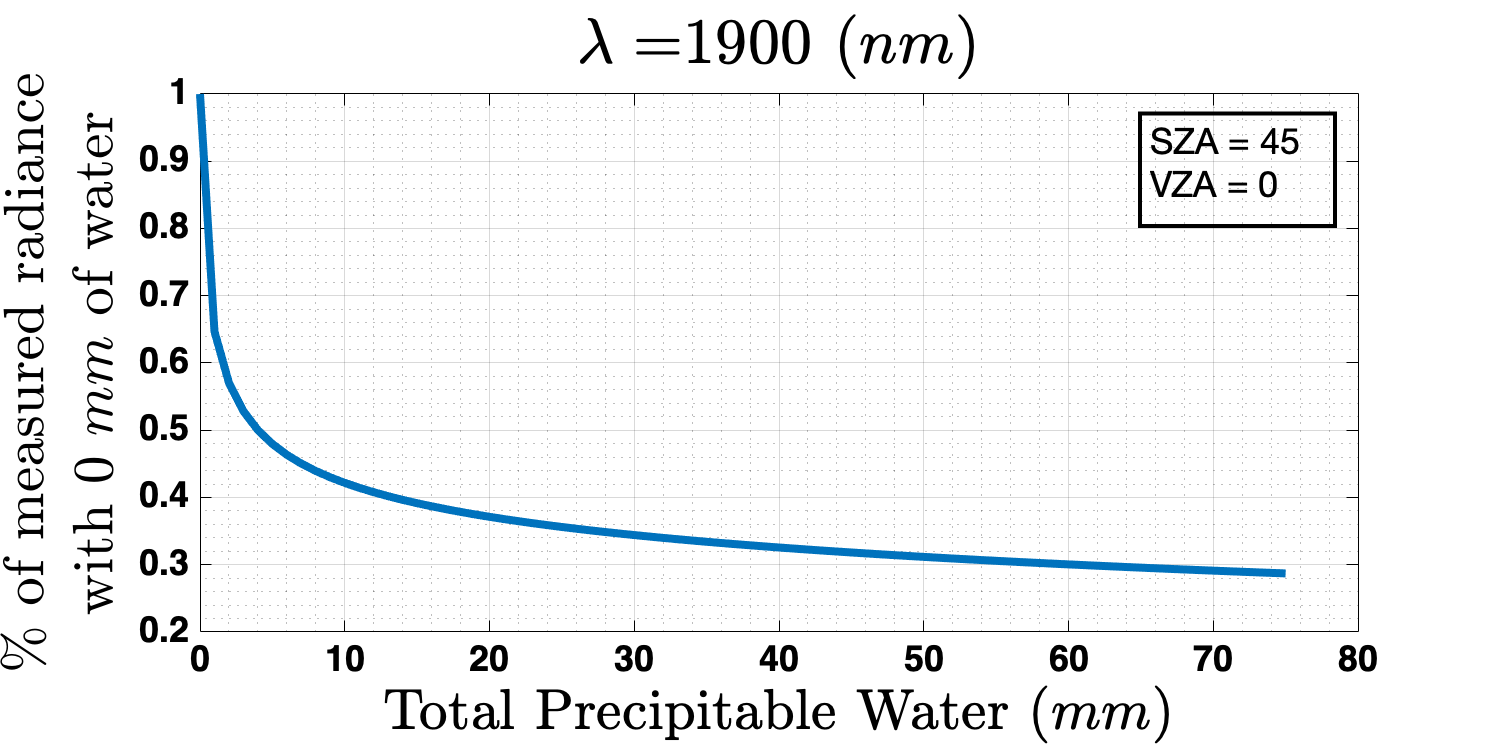

% How does the radiance measured at TOA change with the scaled total
% precipitable water?

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'with 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',4)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

Wow! At wavelengths where the absorption coefficient of water vapor is high, a measurement from space can drop significantly! But it's interesting to point out that most of the change happens after adding 10 $mm$ of precipictable water. In fact thats almost 90% of the change when adding 75 $mm$ of precipitable water! Yesterday, the total column water vapor amount retrieved by the AMSR2 microwave radiometer was about 8mm. So even in a dry place like Boulder, water vapor can affect reflectance measurements at wavelengths where water vapor strongly absorbs.

#### Within the regions where water vapor strongly absorbs, does solar zenith angle strongly affect the measured radiance?

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 1900;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 0;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree


% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")


#### Make Plots!

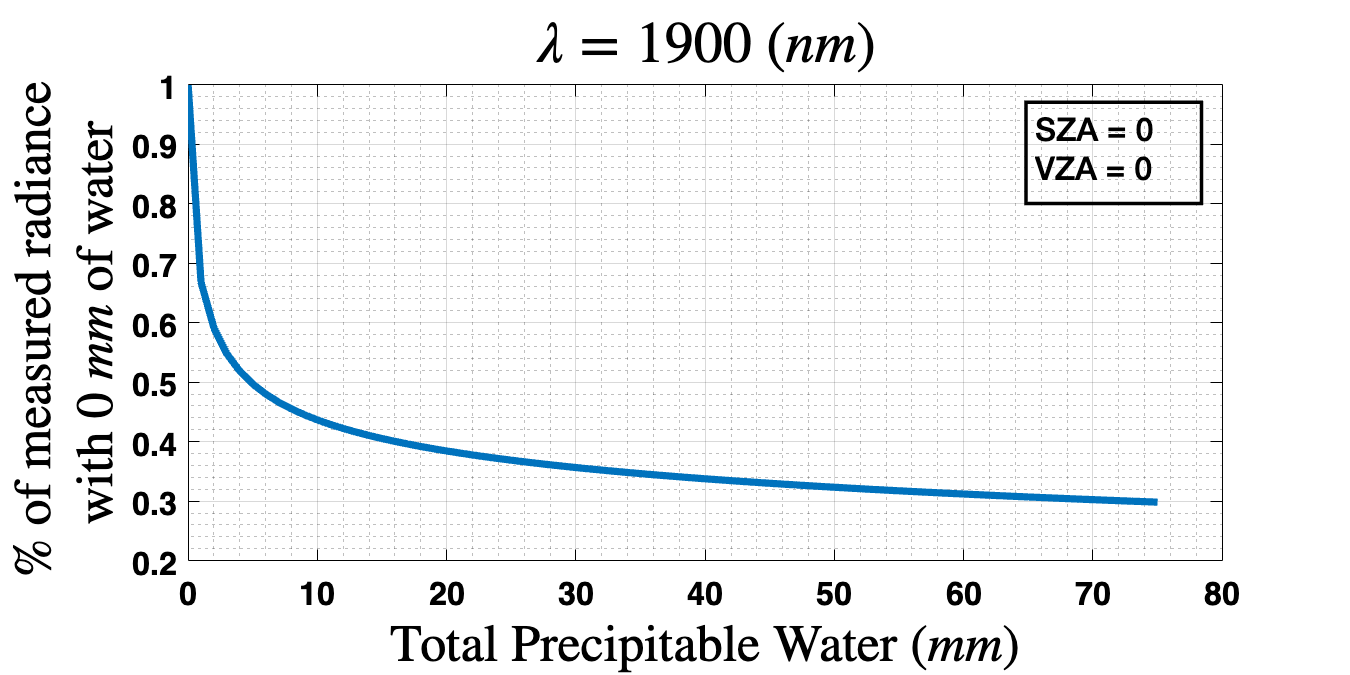

% How does the radiance measured at TOA change with the scaled total
% precipitable water?

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'for 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

#### Lets combine all calculations into a single plot

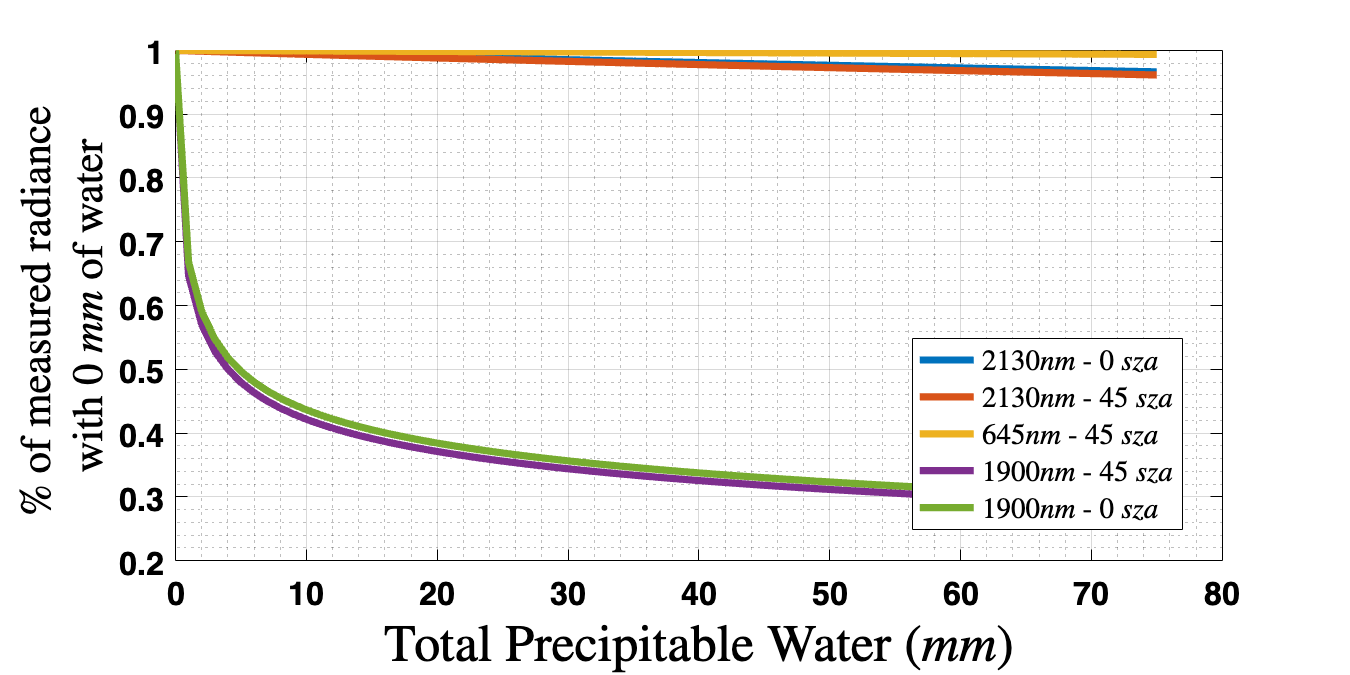

% Load the measured radiance at 2130 nm with 0 solar zenith angle
rad_toa_2130nm_0sza = load("2130nm_rad_toa_0sza_afglsw.mat","rad_toa", "total_h2O_column");

% Load the measured radiance at 2130 nm with 45 solar zenith angle
rad_toa_2130nm_45sza = load("2130nm_rad_toa_45sza_afglsw.mat","rad_toa");

% Load the measured radiance at 645 nm with 45 solar zenith angle
rad_toa_645nm_45sza = load("645nm_rad_toa_45sza_afglsw.mat","rad_toa");

% Load the measured radiance at 1900 nm with 45 solar zenith angle
rad_toa_1900nm_45sza = load("1900nm_rad_toa_45sza_afglsw.mat","rad_toa");

% Load the measured radiance at 1900 nm with 0 solar zenith angle
rad_toa_1900nm_0sza = load("1900nm_rad_toa_0sza_afglsw.mat","rad_toa");


figure;
plot(rad_toa_2130nm_0sza.total_h2O_column, rad_toa_2130nm_0sza.rad_toa/rad_toa_2130nm_0sza.rad_toa(1))
hold on;
plot(rad_toa_2130nm_0sza.total_h2O_column, rad_toa_2130nm_45sza.rad_toa/rad_toa_2130nm_45sza.rad_toa(1))
plot(rad_toa_2130nm_0sza.total_h2O_column, rad_toa_645nm_45sza.rad_toa/rad_toa_645nm_45sza.rad_toa(1))
plot(rad_toa_2130nm_0sza.total_h2O_column, rad_toa_1900nm_45sza.rad_toa/rad_toa_1900nm_45sza.rad_toa(1))
plot(rad_toa_2130nm_0sza.total_h2O_column, rad_toa_1900nm_0sza.rad_toa/rad_toa_1900nm_0sza.rad_toa(1))

grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'for 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',24)
legend('$2130 nm$ - 0 $sza$','$2130 nm$ - 45 $sza$','$645 nm$ - 45 $sza$','$1900 nm$ - 45 $sza$',...
    '$1900 nm$ - 0 $sza$', 'Interpreter','latex','Location','best')

set(gcf,'Position', [0 0 750, 375])

So we can see that solar senith angle does not play a large role for TOA measured radiance for a cloudless atmosphere. Even within spectral regions where water vapor strongly absorbs, a change in zenith angle does not change the amount of photons that scatter back into space. What primarily matters is the bulk absorption coefficient of water vapor.

## Keep total column water vapor constant, but alter the vertical profile

It's clear from the above plots that atmospheric water vapor can affect measurements from space if at the wavelength chosen, water vapor has a high bulk absorption coefficient. Therefore the presence of water vapor affects the retrieval of droplet size by tricking the retrieval into thinking the droplet size is larger than it is because of the added absorption of water vapor.

But what happens if the amount of precipitable water is the same, but the vertical profiles are drastically different?

#### Computed radiance for the same atmosphere as above, but with a flipped $H_2O$ profile

So the atmospheric water vapor increases towards the top of the atmosphere

% Load the input file and edit the total water vapor column during each iteration

total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree


% define the atmospheric data file
atm_file = 'afglsw_flipped_h2o.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{rr,tt}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    %formatSpec = '%s %s %5s %s \n';
    %fprintf(fileID, formatSpec,'cloudcover wc', num2str(cloud_cover), ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    % formatSpec = '%s %s %5s %s \n\n';
    % fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")

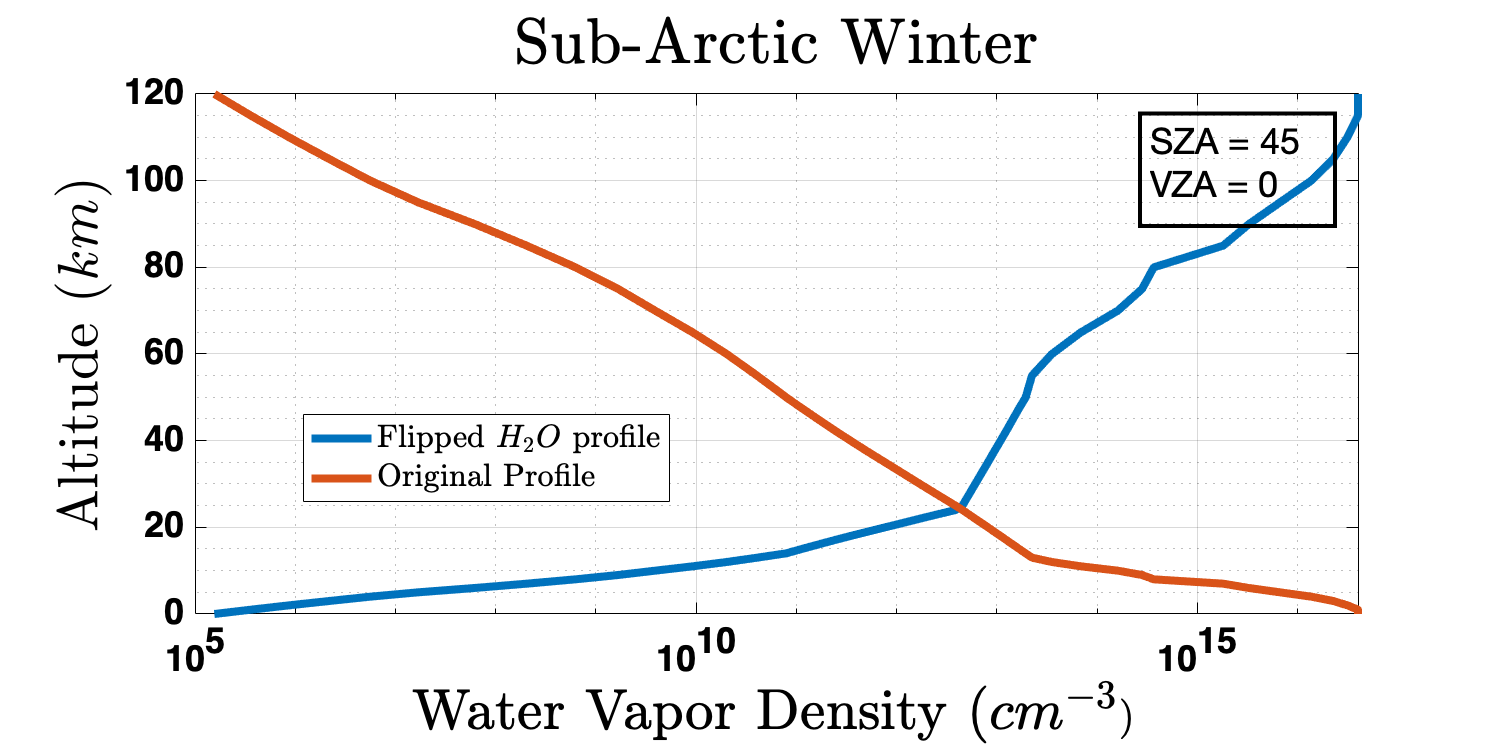

% Compare the original water vapor profile from the AFGL Sub-Arctic Winter
% with the flipped water vapor profile

% Load the Air Force Geophysical Laboratory's Sub-Arctic Winter atmsophere
atm = read_atmos_prof_data('AFGLSW.dat');
atm_flipped = read_atmos_prof_data('AFGLSW_flipped_h2o.dat');


figure;
semilogx(atm_flipped.H2O, atm_flipped.altitude);
hold on;
semilogx(atm.H2O, atm.altitude);
grid on; grid minor
% Create textbox of solar and viewing zenith angles
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
legend('Flipped $H_2O$ profile','Original Profile', 'Interpreter','latex','Location','best')
xlabel('Water Vapor Density ($cm^{-3}$)','Interpreter','latex')
ylabel('Altitude ($km$)','Interpreter','latex')
title('Sub-Arctic Winter','Interpreter','latex')
set(gcf,'Position', [0 0 750, 375])

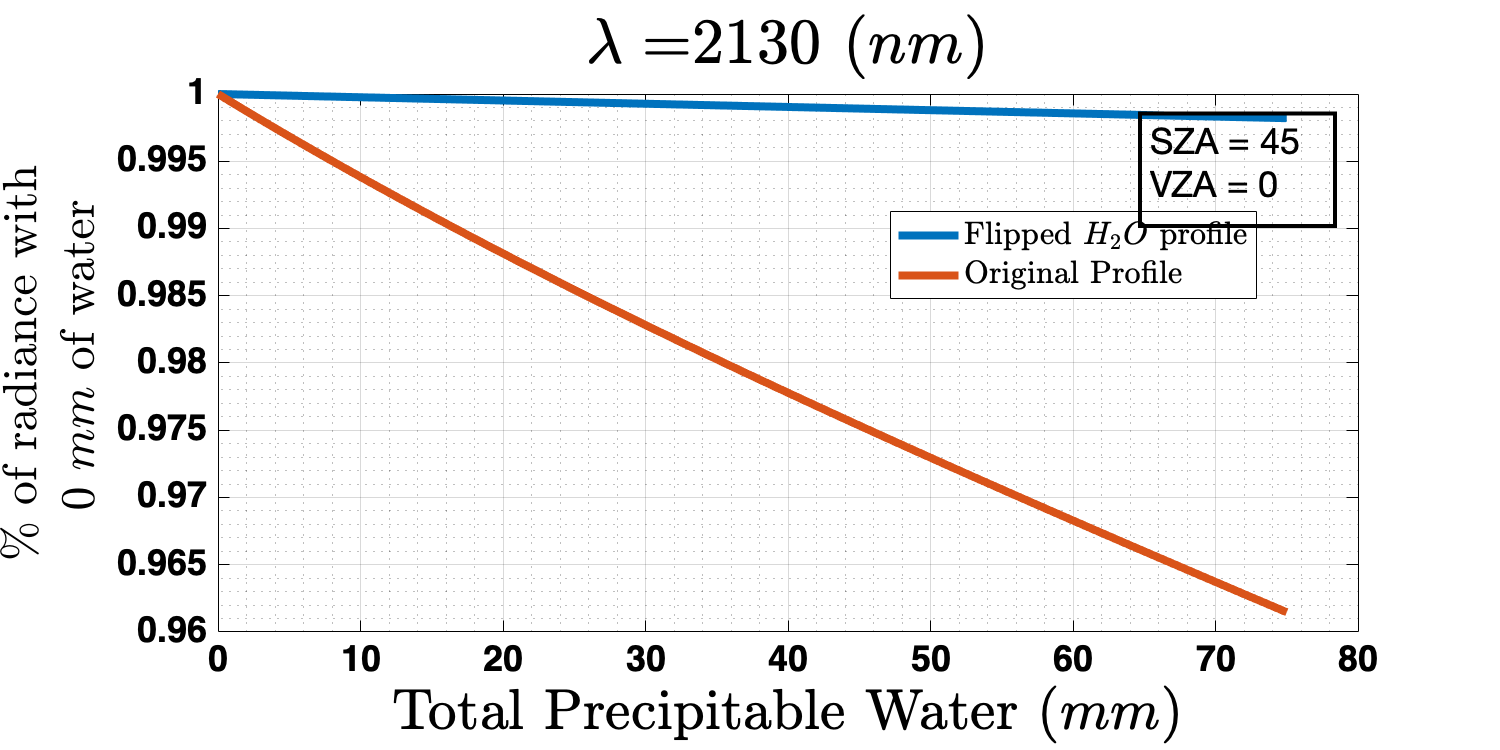


% How does the radiance measured at TOA change with the scaled total
% precipitable water? How does it compare with the original profile?

non_flipped_rad = load("2130nm_rad_toa_45sza_afglsw.mat","rad_toa");

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
hold on;
plot(total_h2O_column, non_flipped_rad.rad_toa/non_flipped_rad.rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'for 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
legend('Flipped $H_2O$ profile','Original Profile', 'Interpreter','latex','Location','best')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

We can see that the vertical profile of water vapor does indeed affect the top-of-atmosphere radiance measurement. When most of the precipitable water is at the top of the atmosphere, the radiance measurements hardly change with a changing amount of total precipitable water. When most of the water is at the bottom of the atmosphere, the measurements decrease slightly with increasing water amount. Why? Is this due to the scattering properties of water vapor? For a 1D nadir line of sight, scattering events higher in the atmosphere the angle light has to scatter into becomes smaller. At locations deeper in the atmosphere, close to the surface, the scattering angle is largest. Can this explain the difference in the above curves? 

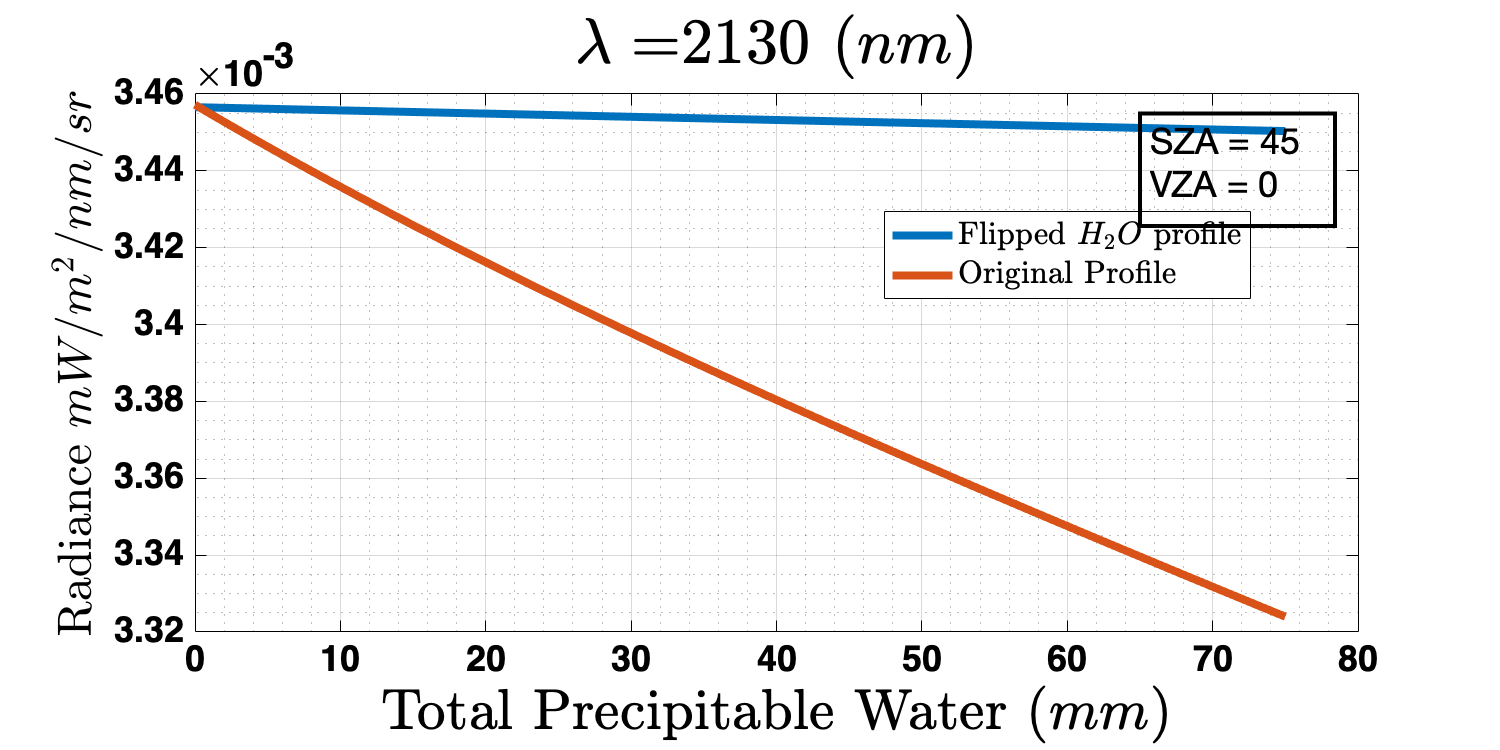

% What do the absolute values look like?

figure;
plot(total_h2O_column, rad_toa)
hold on;
plot(total_h2O_column, non_flipped_rad.rad_toa)
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel('Radiance  $mW/m^{2}/nm/sr$', 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
legend('Flipped $H_2O$ profile','Original Profile', 'Interpreter','latex','Location','best')
% Create textbox
annotation('textbox',[0.76 0.6986 0.13 0.15],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)]},...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

It makes sense that the values where total precipitable water are 0 are identical, because the two atmospheres are the same under this condition. Then the addition of water vapor will only reduce the measurement because water vapor predominantly absorbs across the solar spectral range

## If the optical depth is the important quantity in the radiative transfer equation, then it shouldn't matter what the specific vertical profile of the extinction coefficient is, as long as the integrated quantites are the same. Right? I think what does matter is the scattering phase function, which is not integrated. 

## What happens if we have a cloud layer? 

The presence of water droplets will scatter more light back into space. The presence of above cloud water vapor only affects our measurements by further attenuating the radiation, reducing our measurements and tricking our retrieval algorithm into thinking the cloud layer has larger droplets than it actually does.

% Model the same scenario as above, 2130 reflectance with a solar zenith
% angle of 45 degrees, but with a homogenous cloud layer


total_h2O_column = 0:75;        % mm of precipitable water

rad_toa = zeros(1,length(total_h2O_column));        % Store the radiance measured at TOA

% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree

% -----------------------------------
% ---- Write a Water Cloud file! ----
% -----------------------------------
% define the droplet size
re = 10;                        % microns
% define the total cloud optical depth
tau_c = 25;
% define the geometric location of the cloud top and cloud bottom
z_topBottom = [1.5,1];          % km above surface
% define the type of droplet distribution
distribution_str = 'mono';
% define whether this is a vertically homogenous cloud or not
homogeneous_str = 'homogeneous';
% define how liquid water content will be computed
parameterization_str = 'mie';


wc_filename = write_wc_file(re,tau_c,z_topBottom, wavelength, distribution_str,...
    homogeneous_str, parameterization_str);
% --------------------------------------------------------------

% Define the percentage of cloud cover
percent_cloud_cover = 1;

% Define the parameterization scheme used to comptue the optical quantities
wc_parameterization = 'mie interpolate';


% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_withCloudLayer_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(total_h2O_column)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(nn),' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{1}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'cloudcover wc', percent_cloud_cover, ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_',num2str(sza),'_withCloud_sza_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column")


#### Make plots

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'for 0 $mm$ of water'], 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.675 0.6 0.2225 0.25],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)],...
    ['Cloud Top = ',num2str(z_topBottom(1)),' km'], ...
    ['$\tau_c$ = ',num2str(tau_c)]},...
    'Interpreter','latex',...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

Wow! The change in our measurement changes a lot!!! And this is for a MODIS band that deliberately avoids water vapor! What's going on?


% Plot the comparison between two identical calculations but where one has
% a cloud layer and one does not

no_cloud_2130_rad = load("2130nm_rad_toa_45sza_afglsw.mat","rad_toa");

figure;
plot(total_h2O_column, rad_toa/rad_toa(1))
hold on;
plot(total_h2O_column, no_cloud_2130_rad.rad_toa/no_cloud_2130_rad.rad_toa(1))
grid on; grid minor
xlabel('Total Precipitable Water ($mm$)', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance compared',newline,'with 0 $mm$ of precipitable water'], 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
legend('With cloud layer','Without cloud layer', 'Interpreter','latex','Location','southwest')
% Create textbox
annotation('textbox',[0.675 0.6 0.2225 0.25],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)],...
    ['Cloud Top = ',num2str(z_topBottom(1)),' km'], ...
    ['$\tau_c$ = ',num2str(tau_c)]},...
    'Interpreter','latex',...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

What is the cause of this difference? There is water vapor within the cloud layer. Multiple scattering of light within the cloud increases the chance of absorption, both due to liquid water droplets but also due to the increase in water vapor. This plot, I believe, highlights the effects of multiple scattering. 

#### Is the difference in TOA reflectance in the above plot due to the increased absorption from multiple scattering within the cloud? 

LibRadTran computes the optical depth due to molecular absorption at each level within the atmosphering model. Let's plot the molecular absorption optical depth for 3 different atmospheres: 1 where the total percipitable water vapor is 0mm, one where its 4mm, and one where its 75

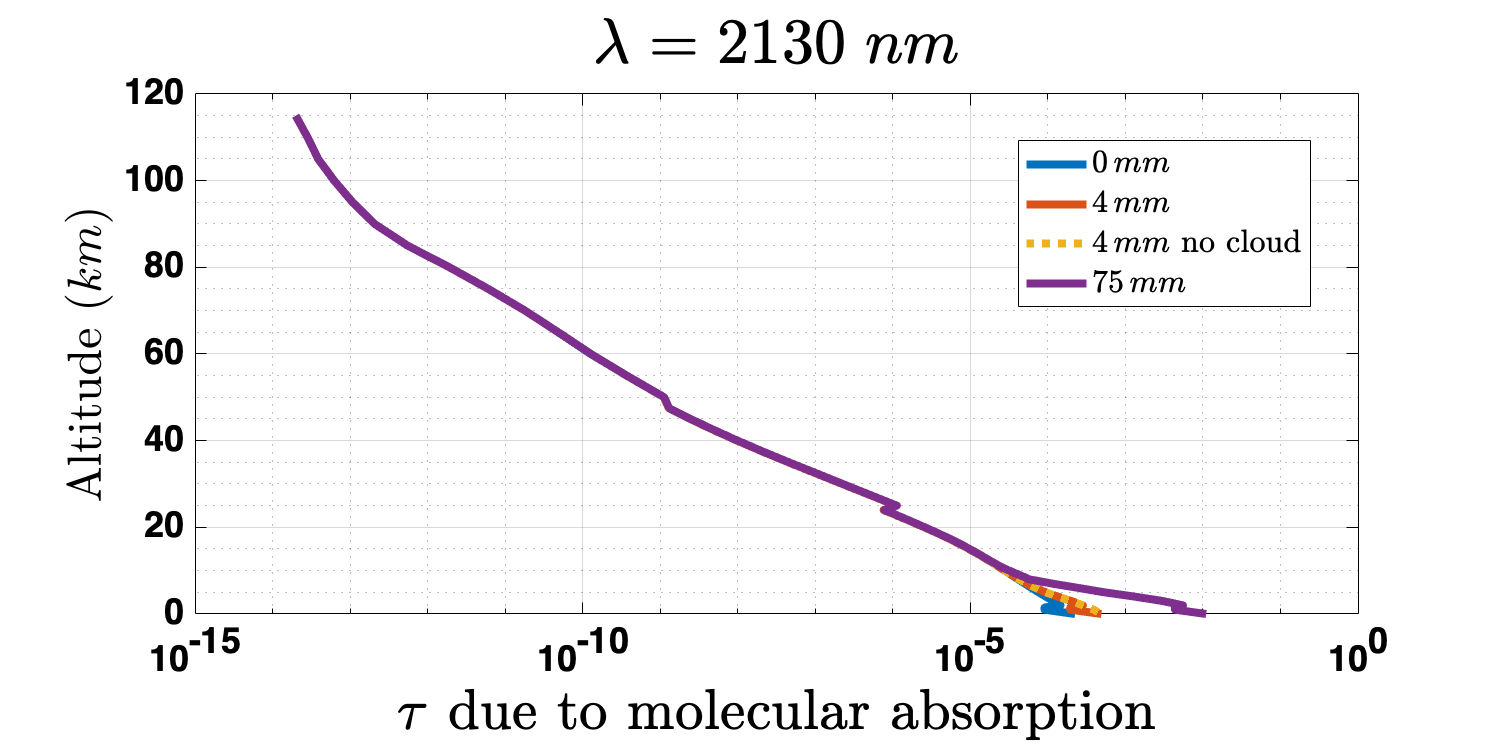

molec_abs_optical_depth = load("2130nm_libRadTran_computed_molecular_absorption_0mm_and_75mm_withCloud.mat");

figure;
semilogx(molec_abs_optical_depth.molec_abs_0mm, molec_abs_optical_depth.z)
hold on;
semilogx(molec_abs_optical_depth.molec_abs_4mm, molec_abs_optical_depth.z)
semilogx(molec_abs_optical_depth.molec_abs_4mm_noCloud, molec_abs_optical_depth.z_noCloud,':')
semilogx(molec_abs_optical_depth.molec_abs_75mm, molec_abs_optical_depth.z)

grid on; grid minor
xlabel('$\tau$ due to molecular absorption', 'Interpreter','latex')
ylabel('Altitude ($km$)', 'Interpreter','latex', 'FontSize',24)
title('$\lambda = 2130 \;nm$', 'Interpreter','latex')
legend('$0\,mm$','$4\,mm$','$4\,mm$ no cloud','$75\,mm$', 'Interpreter','latex','Location','best')
set(gcf,'Position', [0 0 750, 375])

Ok, clearly we need to zoom in on the lower 20 kilometers to see what the difference is!

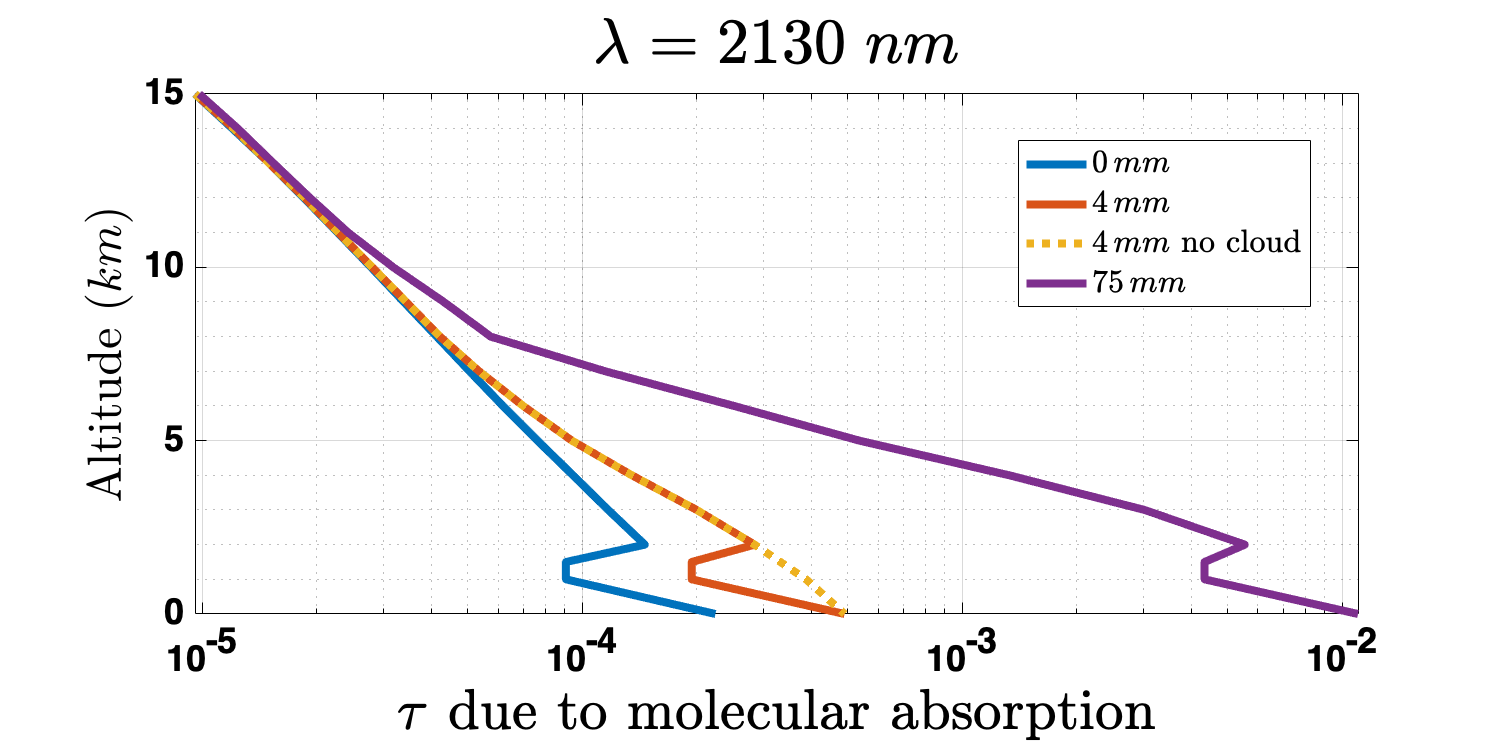

figure;
semilogx(molec_abs_optical_depth.molec_abs_0mm, molec_abs_optical_depth.z)
hold on;
semilogx(molec_abs_optical_depth.molec_abs_4mm, molec_abs_optical_depth.z)
semilogx(molec_abs_optical_depth.molec_abs_4mm_noCloud, molec_abs_optical_depth.z_noCloud,':')
semilogx(molec_abs_optical_depth.molec_abs_75mm, molec_abs_optical_depth.z)

ylim([0,15])
grid on; grid minor
xlabel('$\tau$ due to molecular absorption', 'Interpreter','latex')
ylabel('Altitude ($km$)', 'Interpreter','latex', 'FontSize',24)
title('$\lambda = 2130 \;nm$', 'Interpreter','latex')
legend('$0\,mm$','$4\,mm$','$4\,mm$ no cloud','$75\,mm$', 'Interpreter','latex','Location','best')
set(gcf,'Position', [0 0 750, 375])

So molecular absorption decreases within the cloud (between 1 and 1.5 km), and increases above cloud between 1.5 and 2 km. Why? This figure suggests the biggest effect is not increased absorption within the cloud, but increased absorption above the cloud. But optical depth does not caputure multiple scattering processes. 

#### Off the coast of Chile, marine stratus clouds are often found. Column water vapor amounts according to the AMSR microwave radiometer are about 15-20 mm of precipitable water. How does the TOA radiance change with changing cloud optical thickness for this fixed amount of column water vapor?

% Model an atmosphere with a fixed amount of column water vapor, with a
% changing cloud optical depth


total_h2O_column = 17;        % mm of precipitable water


% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree

% -----------------------------------
% ---- Write a Water Cloud file! ----
% -----------------------------------

% define the total cloud optical depth
tau_c = 1:40;
% define the droplet size
re = linspace(10,10,length(tau_c));                        % microns
% define the geometric location of the cloud top and cloud bottom
z_topBottom = [1.5,1];          % km above surface
% define the type of droplet distribution
distribution_str = 'mono';
% define whether this is a vertically homogenous cloud or not
homogeneous_str = 'homogeneous';
% define how liquid water content will be computed
parameterization_str = 'mie';



wc_filename = write_wc_file(re,tau_c,z_topBottom, wavelength, distribution_str,...
    homogeneous_str, parameterization_str);
% --------------------------------------------------------------

rad_toa = zeros(1,length(tau_c));        % Store the radiance measured at TOA


% Define the percentage of cloud cover
percent_cloud_cover = 1;

% Define the parameterization scheme used to comptue the optical quantities
wc_parameterization = 'mie interpolate';


% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_withCloudLayer_changing-waterVapor_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];




for nn = 1:length(tau_c)

    % ---- ****************** ------
    % ---- Write the INP File ------
    % ---- ****************** ------

    % Open the old file for writing
    fileID = fopen([folderName,inputName], 'w');

    % Define which RTE solver to use
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


    % Define the number of streams to keep track of when solving the equation
    % of radiative transfer
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


    % Define the location and filename of the atmopsheric profile to use
    % ------------------------------------------------
    formatSpec = '%s %5s %s \n';
    fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

    % Define the location and filename of the extraterrestrial solar source
    % ---------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


    % Define the total precipitable water
    % ------------------------------------------------
    formatSpec = '%s %s %f %s %5s %s \n';
    fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column,' MM', ' ', '# Total Precipitable Water');


    % Define the surface albedo
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


    % Define the water cloud file
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{nn}], ' ', '# Location of water cloud file');


    % Define the percentage of horizontal cloud cover
    % This is a number between 0 and 1
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'cloudcover wc', percent_cloud_cover, ' ', '# Cloud cover percentage');


    % Define the technique or parameterization used to convert liquid cloud
    % properties of r_eff and LWC to optical depth
    % ----------------------------------------------------------------------
    formatSpec = '%s %s %5s %s \n\n';
    fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


    % Define the wavelengths for which the equation of radiative transfer will
    % be solve
    % -------------------------------------------------------------------------
    formatSpec = '%s %f %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


    % Define the sensor altitude
    % ------------------------------------------------
    formatSpec = '%s %s %5s %s \n';
    fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

    % Define the solar zenith angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

    % Define the solar azimuth angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

    % Define the cosine of the zenith viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n';
    fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

    % Define the azimuth viewing angle
    % ------------------------------------------------
    formatSpec = '%s %f %5s %s \n\n';
    fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


    % Set the error message to quiet of verbose
    % ------------------------------------------------
    formatSpec = '%s';
    fprintf(fileID, formatSpec,'verbose');


    % Close the file!
    fclose(fileID);
    % ----------------------------------------------------
    % ----------------------------------------------------

    % Run the INP file
    inputSettings = runUVSPEC(folderName,inputName,outputName);

    % Grab and store the radiance
    [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

    rad_toa(nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_withCloud_',num2str(sza),'_sza_changingTau_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column","tau_c")


#### Make Plots!

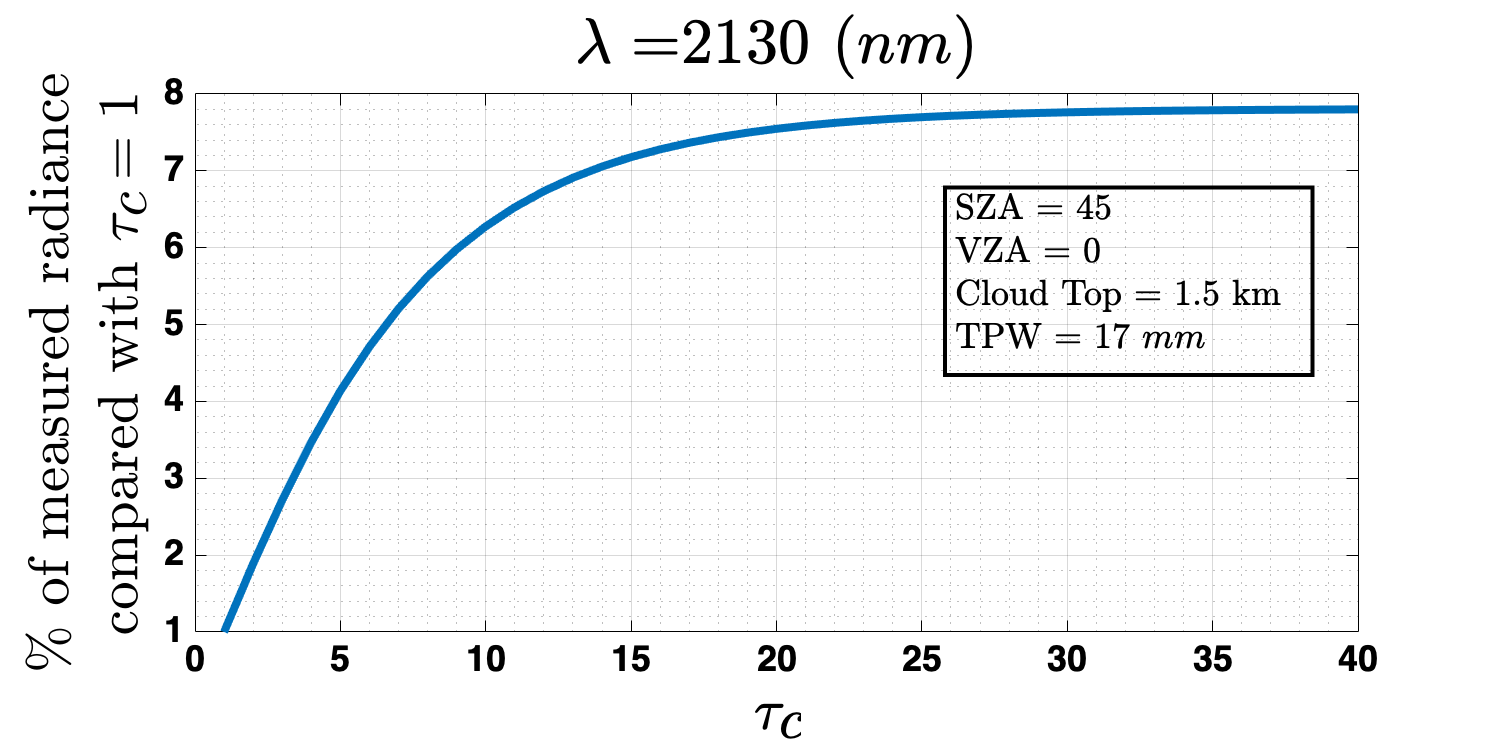

figure;
plot(tau_c, rad_toa/rad_toa(1))
grid on; grid minor
xlabel('$\tau_c$', 'Interpreter','latex')
ylabel(['$\%$ of measured radiance ',newline,'compared with $\tau_c =1$'], 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
% Create textbox
annotation('textbox',[0.63 0.5 0.245 0.25],...
    'String',{['SZA = ',num2str(sza)],['VZA = ',num2str(vza)],...
    ['Cloud Top = ',num2str(z_topBottom(1)),' km'], ...
    ['TPW = ',num2str(total_h2O_column),' $mm$']},...
    'Interpreter','latex',...
    'LineWidth',2,...
    'FontSize',18,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 750, 375])

OK, so the TOA reflectance asymptotes to a value 8 times as great as the value when the optical depth is 1. But how does water vapor play a role?

#### Let's run the same calcualtion, but lets vary the total precipitable water for each optical depth. Then plot this as a 2D colormap as a function of the value when the optical depth is 1 and the water vapor amount is 0mm

#### Off the coast of Chile, marine stratus clouds are often found. Column water vapor amounts according to the AMSR microwave radiometer are about 15-20 mm of precipitable water. How does the TOA radiance change with changing cloud optical thickness for this fixed amount of column water vapor?

% Model an atmosphere with a fixed amount of column water vapor, with a
% changing cloud optical depth


total_h2O_column = 0:75;        % mm of precipitable water


% define the wavelength
wavelength = 2130;              % nm - monochromatic wavelength calcualtion

% define the solar zenith angle
sza = 45;                       % degree

% define the viewing zenith angle
vza = 0;                        % degree

% -----------------------------------
% ---- Write a Water Cloud file! ----
% -----------------------------------

% define the total cloud optical depth
tau_c = 1:40;
% define the droplet size
re = linspace(10,10,length(tau_c));                        % microns
% define the geometric location of the cloud top and cloud bottom
z_topBottom = [1.5,1];          % km above surface
% define the type of droplet distribution
distribution_str = 'mono';
% define whether this is a vertically homogenous cloud or not
homogeneous_str = 'homogeneous';
% define how liquid water content will be computed
parameterization_str = 'mie';



wc_filename = write_wc_file(re,tau_c,z_topBottom, wavelength, distribution_str,...
    homogeneous_str, parameterization_str);
% --------------------------------------------------------------

rad_toa = zeros(length(total_h2O_column),length(tau_c));        % Store the radiance measured at TOA


% Define the percentage of cloud cover
percent_cloud_cover = 1;

% Define the parameterization scheme used to comptue the optical quantities
wc_parameterization = 'mie interpolate';


% define the atmospheric data file
atm_file = 'afglsw.dat';

% define the name of the changing input file
inputName = [num2str(wavelength),'nm_withCloudLayer_changing-waterVapor_changing-tau_',atm_file(1:end-4),'.INP'];

% Define the .OUT file name
outputName = ['OUTPUT_',inputName(1:end-4)];



for ww = 1:length(total_h2O_column)
    for nn = 1:length(tau_c)

        % ---- ****************** ------
        % ---- Write the INP File ------
        % ---- ****************** ------

        % Open the old file for writing
        fileID = fopen([folderName,inputName], 'w');

        % Define which RTE solver to use
        % ------------------------------------------------
        formatSpec = '%s %s %5s %s \n';
        fprintf(fileID, formatSpec,'rte_solver','disort',' ', '# Radiative transfer equation solver');


        % Define the number of streams to keep track of when solving the equation
        % of radiative transfer
        % ------------------------------------------------
        formatSpec = '%s %s %5s %s \n\n';
        fprintf(fileID, formatSpec,'number_of_streams','6',' ', '# Number of streams');


        % Define the location and filename of the atmopsheric profile to use
        % ------------------------------------------------
        formatSpec = '%s %5s %s \n';
        fprintf(fileID, formatSpec,['atmosphere_file ','../data/atmmod/',atm_file],' ', '# Location of atmospheric profile');

        % Define the location and filename of the extraterrestrial solar source
        % ---------------------------------------------------------------------
        formatSpec = '%s %s %5s %s \n\n';
        fprintf(fileID, formatSpec,'source solar','../data/solar_flux/kurudz_1.0nm.dat', ' ', '# Bounds between 250 and 10000 nm');


        % Define the total precipitable water
        % ------------------------------------------------
        formatSpec = '%s %s %f %s %5s %s \n';
        fprintf(fileID, formatSpec,'mol_modify','H2O', total_h2O_column(ww),' MM', ' ', '# Total Precipitable Water');


        % Define the surface albedo
        % ------------------------------------------------
        formatSpec = '%s %s %5s %s \n\n';
        fprintf(fileID, formatSpec,'albedo','0', ' ', '# Surface albedo of the ocean');


        % Define the water cloud file
        % ------------------------------------------------
        formatSpec = '%s %s %5s %s \n';
        fprintf(fileID, formatSpec,'wc_file 1D', ['../data/wc/',wc_filename{nn}], ' ', '# Location of water cloud file');


        % Define the percentage of horizontal cloud cover
        % This is a number between 0 and 1
        % ------------------------------------------------
        formatSpec = '%s %f %5s %s \n';
        fprintf(fileID, formatSpec,'cloudcover wc', percent_cloud_cover, ' ', '# Cloud cover percentage');


        % Define the technique or parameterization used to convert liquid cloud
        % properties of r_eff and LWC to optical depth
        % ----------------------------------------------------------------------
        formatSpec = '%s %s %5s %s \n\n';
        fprintf(fileID, formatSpec,'wc_properties', wc_parameterization, ' ', '# optical properties parameterization technique');


        % Define the wavelengths for which the equation of radiative transfer will
        % be solve
        % -------------------------------------------------------------------------
        formatSpec = '%s %f %f %5s %s \n\n';
        fprintf(fileID, formatSpec,'wavelength', wavelength, wavelength, ' ', '# Wavelength range');


        % Define the sensor altitude
        % ------------------------------------------------
        formatSpec = '%s %s %5s %s \n';
        fprintf(fileID, formatSpec,'zout', 'toa', ' ', '# Sensor Altitude');

        % Define the solar zenith angle
        % ------------------------------------------------
        formatSpec = '%s %f %5s %s \n';
        fprintf(fileID, formatSpec,'sza', sza, ' ', '# Solar zenith angle');

        % Define the solar azimuth angle
        % ------------------------------------------------
        formatSpec = '%s %f %5s %s \n';
        fprintf(fileID, formatSpec,'phi0', 0.0, ' ', '# Solar azimuth angle');

        % Define the cosine of the zenith viewing angle
        % ------------------------------------------------
        formatSpec = '%s %f %5s %s \n';
        fprintf(fileID, formatSpec,'umu', cosd(vza), ' ', '# Cosine of the zenith viewing angle');

        % Define the azimuth viewing angle
        % ------------------------------------------------
        formatSpec = '%s %f %5s %s \n\n';
        fprintf(fileID, formatSpec,'phi', 0.0, ' ', '# Azimuthal viewing angle');


        % Set the error message to quiet of verbose
        % ------------------------------------------------
        formatSpec = '%s';
        fprintf(fileID, formatSpec,'verbose');


        % Close the file!
        fclose(fileID);
        % ----------------------------------------------------
        % ----------------------------------------------------

        % Run the INP file
        inputSettings = runUVSPEC(folderName,inputName,outputName);

        % Grab and store the radiance
        [ds,~,~] = readUVSPEC(folderName,outputName,inputSettings(2,:));

        rad_toa(ww,nn) = ds.radiance.rad_umu_phi;          % mW/m^2/nm/sr

    end
end

% Let's save this curve to compare with later calculations
save([num2str(wavelength),'nm_rad_toa_withCloud_',num2str(sza),'_sza_changingTau_',atm_file(1:end-4),'.mat'],...
    "rad_toa", "total_h2O_column","tau_c")


#### How does the TOA radiance change with optical depth and with total precipitable water?

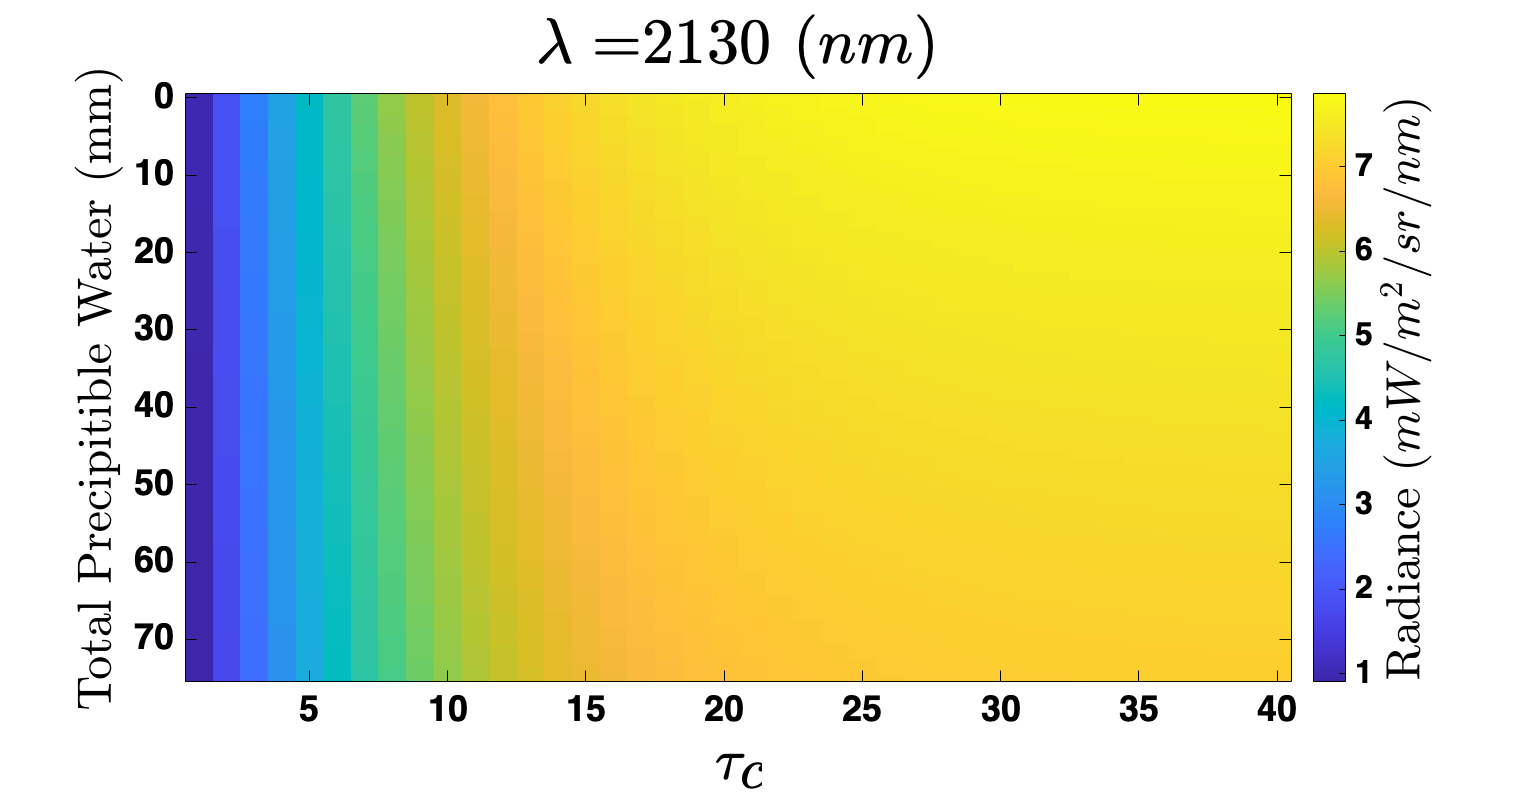

figure;
imagesc(tau_c, total_h2O_column, rad_toa)
xlabel('$\tau_c$', 'Interpreter','latex')
ylabel('Total Precipitible Water (mm)', 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
cb = colorbar;
cb.Label.String = 'Radiance ($mW/m^{2}/sr/nm$)';
cb.Label.Interpreter = 'latex';
cb.Label.FontSize = 24;
% Create textbox
annotation('textbox',[0.749684210526316 0.9125 0.0950526315789474 0.0675000000000002],...
    'String',['SZA = ',num2str(sza)],...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');
set(gcf,'Position', [0 0 760, 400])

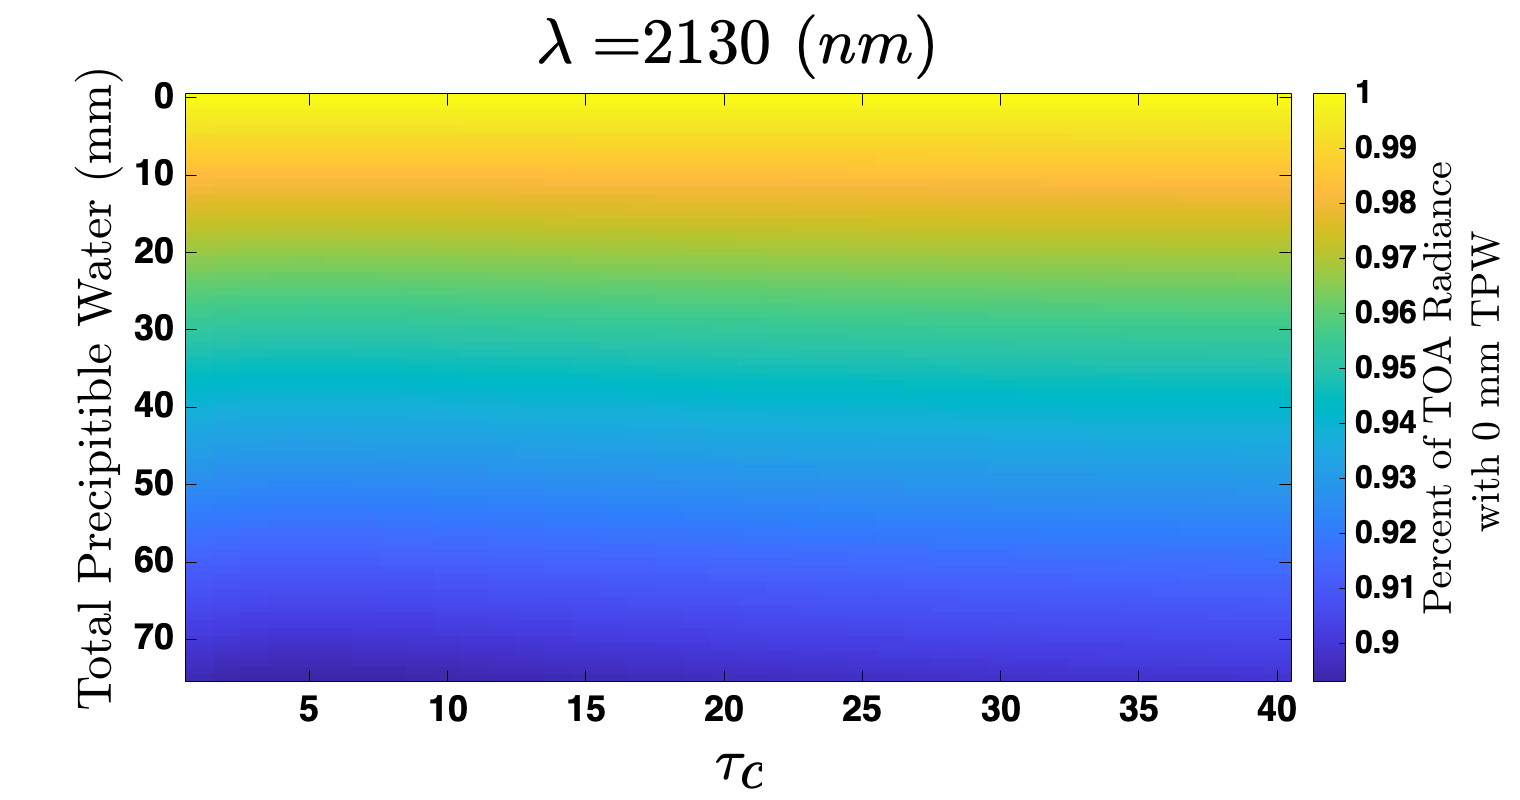


figure;
imagesc(tau_c, total_h2O_column, rad_toa./repmat(rad_toa(1,:),length(total_h2O_column),1))
xlabel('$\tau_c$', 'Interpreter','latex')
ylabel('Total Precipitible Water (mm)', 'Interpreter','latex', 'FontSize',24)
title(['$\lambda = $',num2str(wavelength),' ($nm$)'], 'Interpreter','latex')
cb = colorbar;
cb.Label.String = ['Percent of TOA Radiance',newline,' with 0 mm TPW'];
cb.Label.Interpreter = 'latex';
cb.Label.FontSize = 20;
% Create textbox
annotation('textbox',[0.749684210526316 0.9125 0.0950526315789474 0.0675000000000002],...
    'String',['SZA = ',num2str(sza)],...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Helvetica Neue',...
    'FitBoxToText','off');


set(gcf,'Position', [0 0 760, 400])

So, what did I learn from this? Well, optical depth is the dominant factor in TOA radiance. Precipitable water vapor does matter, but it only changes the TOA radiance by about 10% no matter what the optical depth is. This suggest that the multiple scattering effects don't dramatically increase absorption due to water vapor. If it did, we would expect deeper clouds to see more absorption from atmospheres with more water vapor. This is kind of suprising. It suggests that simple atmospheric attenuation matters more than absorption due to multiple scattering.